# 1 Dimensional Neumman Iterative solution in frequency domain

**Vibration/Acoustic Transducers Lab. **

**Junsu Lee**

## Initialization

clear all
close all
format 'short'
ft_size = 16;

## **Dimensionless Burgers equation in time domain**

The following form of Burgers equation may make it easier to apply the Neumaan iterative soling method :


$$\frac{\partial P}{\partial \xi} - \frac{\delta_0}{2}\frac{\partial^2 P}{\partial \tau^2}  = \frac{\beta_0}{2} \frac{\partial P^2}{\partial \tau} $$


where

 
$$p=p_0P, \\
\xi=x/\lambda_0, \\
\delta_0=\frac{\delta}{c_0 \lambda_0} = \frac{\mu f_0}{\rho_0c_0^2} [4/3+\mu_B/\mu+(\gamma-1)/\text{Pr}], \\
\tau = f_0 t , \\
\beta_0 = \frac{\beta p_0}{\rho_0 c_0^2}.$$


Derivation process :


$$\frac{\partial p}{\partial x} - \frac{\delta}{2 c_0^3}\frac{\partial^2 p}{\partial t^2}  = \frac{\beta p}{ \rho_0 c_0^3} \frac{\partial p}{\partial t}  = \frac{\beta}{2 \rho_0 c_0^3} \frac{\partial p^2}{\partial t} $$



$$\Rightarrow \frac{p_0}{\lambda_0} \frac{\partial P}{\partial \xi} - \frac{\delta p_0 f_0^2}{2 c_0^3}\frac{\partial^2 P}{\partial \tau^2}  = \frac{\beta p_0^2 f_0}{2 \rho_0 c_0^3} \frac{\partial P^2}{\partial \tau} $$


## Physical Properties

### Medium Selection

Pr = 0.71; % Prandtl Number
eta = 1.82*10^-5; % Shear viscosity
gamma = 1.4; % Specific heat ratio
delta=(eta)/1.21*(4/3+0.6+(gamma-1)/Pr); % High freq asymptotic expression
beta = 1.2;
rho0 = 1.21;
c0 = 343;

### **Dimensionless Burgers equation in frequency domain**

We can try to use the Neumann Iterative numerical solving method to the frequency domain form of the Burgers equation, which may be written as follows:


$$\hat{P}^{\prime}(\xi ; n)+\frac{(2 \pi n)^{2} \delta_{0}}{2} \cdot \hat{P}(\xi ; n)=\frac{\beta_{0}}{2} \cdot j 2\pi n[\hat{P}(\xi ; n) \underset{(n)}{*} \hat{P}(\xi ; n)]$$


where $$\hat{P}(\xi ; n)=\int_{-\infty}^{\infty} P(\xi, \tau) e^{-j 2 \pi n \tau} d \tau$ $and $$\hat{P}(\xi ;n) \underset{(n)}{*} \hat{P}(\xi ; n)=\int_{-\infty}^{\infty} \hat{P}(\xi ; v) \cdot \hat{P}(\xi ; n-v) d v$$. Note that $$P(\xi, \tau)=\int_{-\infty}^{\infty} \hat{P}(\xi ; n) e^{j 2 \pi n \tau} dn$$.

Since$ $P(\xi, \tau)$
$ is real, we have the followings:


$${[\hat{P}(\xi ; n)]^{*} }  =\hat{P}(\xi ;-n) 

$$


Let $$\hat{P}(\xi ; n)=\hat{P}_{0}(\xi ; n)+\varepsilon \cdot \hat{P}_{1}(\xi ; n)+\varepsilon^{2} \cdot \hat{P}_{2}(\xi ; n)+\varepsilon^{3} \cdot \hat{P}_{3}(\xi ; n)+\cdots$$ where $$0<\varepsilon= p_0/(\rho_0c_0^2) \ll 1$$,

$$\hat{P}_{0}(0 ; n)=\hat{P}(0 ; n)=\int_{-\infty}^{\infty} P(0, \tau) e^{-j 2 \pi n \tau} d \tau$$ and $$\hat{P}_{i}(0, \tau)=0$$ for all integer $$i \geq 1$
$.

Then,


$$\hat{S}(\xi ; n)=(j 2\pi n) \cdot[\hat{P}(\xi ; n) \underset{(n)}{*} \hat{P}(\xi ; n)]=(j 2\pi n) \cdot \int_{-\infty}^{\infty} \hat{P}(\xi ; v) \cdot \hat{P}(\xi ; n-v) d v \\
 =(j 2\pi n) \cdot \int_{-\infty}^{\infty}\left[\begin{array}{l}
\hat{P}_{0}(\xi ; v)+\varepsilon \hat{P}_{1}(\xi ; v) \\
+\varepsilon^{2} \hat{P}_{2}(\xi ; v)+\varepsilon^{3} \hat{P}_{3}(\xi ; v) \\
+\cdots
\end{array}\right]\left[\begin{array}{l}
\hat{P}_{0}(\xi ; n-v)+\varepsilon \hat{P}_{1}(\xi ; n-v) \\
+\varepsilon^{2} \hat{P}_{2}(\xi ; n-v) \\
+\varepsilon^{3} \hat{P}_{3}(\xi ; n-v)+\cdots
\end{array}\right] d v \\

 =(j 2\pi n) \cdot\left[\hat{P}_{0}(\xi ; n) \underset{(n)}{*} \hat{P}_{0}(\xi ; n)\right]+\varepsilon \cdot(j 2 \pi n) \cdot\left[2 \cdot \hat{P}_{1}(\xi ; n) \underset{(n)}{*} \hat{P}_{0}(\xi ; n)\right] \\
 +\varepsilon^{2} \cdot(j 2\pi n) \cdot\left[\hat{P}_{1}(\xi ; n)  \underset{(n)}{*} \hat{P}_{1}(\xi ; n)+2 \cdot \hat{P}_{2}(\xi ; n) \underset{(n)}{*}  \hat{P}_{0}(\xi ; n)\right] \\
 +\varepsilon^{3} \cdot(j 2\pi n) \cdot\left[2 \cdot \hat{P}_{1}(\xi ; n) \underset{(n)}{*} \hat{P}_{2}(\xi ; n)+2 \cdot \hat{P}_{3}(\xi ; n) \underset{(n)}{*} \hat{P}_{0}(\xi ; n)\right]+\cdots \\
 =\hat{S}_{(0,0)}(\xi ; n)+\varepsilon\left[2 \cdot \hat{S}_{(1,0)}(\xi ; n)\right]+\varepsilon^{2}\left[\hat{S}_{(1,1)}(\xi ; n) + 2 \cdot \hat{S}_{(2,0)}(\xi ; n)\right]  
 +\varepsilon^{2}\left[2 \cdot \hat{S}_{(1,2)}(\xi ; n)+2 \cdot \hat{S}_{(3,0)}(\xi ; n)\right]+\cdots$$


where


$$\hat{S}_{(l, m)}(\xi ; n)  =(j 2\pi n) \cdot \int_{-\infty}^{\infty} \hat{P}_{l}(\xi ; v) \hat{P}_{m}(\xi ; n-v) d v 
 =(j 2\pi n) \cdot \int_{-\infty}^{\infty} \hat{P}_{m}(\xi ; v) \hat{P}_{l}(\xi ; n-v) d v  =\hat{S}_{(m, l)}(\xi ; n) .
$$


Substitute above expression into dimesionless Burgers equation:


$$$\left[\frac{d}{d \xi}+\frac{\delta_0 (2{\pi  n})^{2}}{2} \right]\left[\begin{array}{l}\hat{P}_{0}(\xi ; n)+\varepsilon \hat{P}_{1}(\xi ; n)+\varepsilon^{2} \hat{P}_{2}(\xi ; n)  +\varepsilon^{3} \hat{P}_{3}(\xi ; n)+\cdots\end{array}\right]= \frac{\beta_0}{2} \cdot \hat{S}(\xi ; n)$$$


since $$\beta_{0}=\beta \cdot \varepsilon $$, we have the followings:


$$\left\lbrack \begin{array}{c}
\left(\frac{d\hat{P_0 } }{d\xi \;}+2\pi^2 n^2 \delta_0 \hat{P_0 } \right)\\
+\epsilon \left(\frac{d\hat{P_1 } }{d\xi \;}+2\pi^2 n^2 \delta_0 \hat{P_1 } \right)\\
+\epsilon^2 \left(\frac{d\hat{P_2 } }{d\xi \;}+2\pi^2 n^2 \delta_0 \hat{P_2 } \right)\\
+\ldotp \ldotp \ldotp 
\end{array}\right\rbrack =\frac{\beta }{2}\left\lbrack \begin{array}{c}
\epsilon {\hat{S} }_{\left(0,0\right)} \left(\xi \;;n\right)\\
+\epsilon^2 \left\lbrack 2{\hat{S} }_{\left(1,0\right)} \left(\xi \;;n\right)\right\rbrack \\
+\epsilon^3 \left\lbrack 2{\hat{S} }_{\left(2,0\right)} \left(\xi \;;n\right)+{\hat{S} }_{\left(1,1\right)} \left(\xi \;;n\right)\right\rbrack \\
+\ldotp \ldotp \ldotp 
\end{array}\right\rbrack$$


 In order to satisfy the above equation for any small $$\varepsilon$$, the coefficients for each order of $$\varepsilon$$ should be equal.

0-th order of $\varepsilon$: $\frac{d \hat{P}_{0}}{d \xi}+2 \pi^{2} n^{2} \delta_{0}  \hat{P}_{0} = 0$

$\hat{P}_{0}(\xi ; n)=\hat{P}(0 ; n) e^{-2 \pi^{2} n^{2} \delta_{0}  \xi}$.

First order of $\varepsilon$: $\frac{d \hat{P}_{1}}{d \xi}+2 \pi^{2} n^{2}  \delta_{0} \hat{P}_{1}= \frac{\beta}{2} \hat{S}_{(0,0)}(\xi ; n)$


$$$\hat{P}_{1}(\xi ; n)=\frac{\beta}{2} \int_{0}^{\xi} \hat{S}_{(0,0)}(\zeta ; n) e^{-2 \pi^{2} n^{2} \delta_{0} (\xi-\zeta)} d \zeta$$$


Second order of $\varepsilon$: $\frac{d \hat{P}_{2}}{d \xi}+2 \pi^{2} n^{2} \delta_{0} \hat{P}_{2}=\frac{\beta}{2} 2\hat{S}_{(1,0)}(\xi ; n)$,


$$$\hat{P}_{2}(\xi ; n)=\frac{\beta}{2}\int_{0}^{\xi} 2 \hat{S}_{(1,0)}(\zeta ; n) e^{-2 \pi^{2} n^{2} \delta_{0} (\xi-\zeta)} d \zeta$$$


Third order of $\varepsilon$: $\frac{d \hat{P}_{3}}{d \xi}+2 \pi^{2} n^{2} \delta_{0}  \hat{P}_{3}=\frac{\beta}{2} [2\hat{S}_{(2,0)}(\xi ; n)+\hat{S}_{(1,1)}(\xi ; n)]$,

$\hat{P}_{3}(\xi ; n)=\frac{\beta}{2}\int_{0}^{\xi}\left[2 \hat{S}_{(2,0)}(\zeta ; n)+\hat{S}_{(1,1)}(\zeta ; n)\right] e^{-2 \pi^{2} n^{2} \delta_{0} (\xi-\zeta)} d \zeta$.

Mathematical technique :

 
$$\frac{dy}{dx}+Ay = B \\
\Rightarrow (e^{Ax} y)' = e^{Ax} B \\
\Rightarrow y = e^{-Ax} \int B e^{-Az} dz$$


- n이 positive integer가 아니라 positive real number이므로 n의 resolution을 더욱 높이면 결과가 달라질까? NO

## Implementation of the discrete convolution using dirac delta function

Let $  \[ \hat{P}(\xi ; n)= \sum\limits_{q=-\infty}^{\infty} \hat{P}(\xi ; q) \cdot \delta(n-q) \] 
$

where 


$$$$
\delta(x)=\left\{\begin{array}{cc}
+\infty ,& x=0\\
0 ,& x\neq0
\end{array} \right.
$$$$


The source term can be rewritten by above the relationship of shape function:


$$$$

\hat{S}_{(l, m)}(\xi ; n)  =(j 2\pi n)  \cdot\left[\hat{P}_{l}(\xi ; n) \underset{(n)}{*} \hat{P}_{m}(\xi ; n)\right] \\
 =(j 2\pi n) \cdot \int_{-\infty}^{\infty} \sum_{q=-\infty}^{\infty} \hat{P}_{l}(\xi ; q) \delta(v-q) \cdot \sum_{r=-\infty}^{\infty} \hat{P}_{m}(\xi ; r) \delta(n-v-r)  d v \\
 =(j 2\pi n) \cdot \sum_{q=-\infty}^{\infty} \sum_{r=-\infty}^{\infty} \hat{P}_{l}(\xi ; q) \hat{P}_{m}(\xi ; r) \int_{-\infty}^{\infty} \delta(v-q)\delta(n-v-r)d v \\
=(j 2\pi n) \cdot \sum_{q=-\infty}^{\infty} \hat{P}_{l}(\xi ; q) \hat{P}_{m}(\xi ; n-q) 
\approx(j 2\pi n) \cdot \sum_{q=-N}^{N} \hat{P}_{l}(\xi ; q) \hat{P}_{m}(\xi ; n-q)
$$$$


## A. Source Selection

Source_type = "Mono";
switch Source_type

### 1. Mono-Frequency Source

case "Mono"
freq_a = 10;
p0 = 10; 282.8427 % 140 [dB]
f0 = freq_a; % Resolution freq.
harmonicNum_a = freq_a/f0;
H_num = [harmonicNum_a];
w_a = 2*pi*freq_a; % Angular freq.

### 2. Bi-Frequency Source

case "Bi"

**2.1. Source Pressure**

p_0a = 10; p_0b = 10; % Initial Pressure
p_comp = [abs(p_0a) abs(p_0b)];
p0 = max(p_comp);
Pa = p_0a/p0; Pb = p_0b/p0; % Normalized Pressure

**2.2. Source Frequencies**

freq_a = 99; freq_b = 101;
f0 = gcd(freq_a,freq_b); % Resolution freq.
harmonicNum_a = freq_a/f0;
harmonicNum_b = freq_b/f0;
H_num = [harmonicNum_a harmonicNum_b];
w_a = 2*pi*freq_a; w_b = 2*pi*freq_b; % Angular freq.

### 3. Multi-Frequency Source

case "Multi"  

**3.1. Source Pressure**

p0 = 10^3; % Initial Pressure
% H_num = 90:110;
% Pn = -1/100*(H_num-100).^2+1; % Normalized Pressure
H_num = 1:10;
Pn = 1+1j*H_num; % Normalized Pressure

**3.2. Source Frequencies**

f0 = 1; % Resolution freq.
% fundamental_freq = 10; 
% T_w = 3/fundamental_freq % width of the envelope
% T_d = 6/fundamental_freq % delay of the envelope
% % Gaussian_source
end

ans = 282.8427

% w0 = 2*pi*f0;
% xbar = (rho0*c0^3)/(beta*w0*p0);
% alpha = delta*w0^2/(2*c0^3); % Absorption coefficient
% A = alpha*xbar; % Dimensionless absorption parameter

## B. Simulation Condition

epsilon = p0/(rho0*c0^2);
% beta_0 = beta*p0/(rho0*c0^2);
% delta_0 = delta*f0/c0^2; 
delta_0 = 0; 

Dimfact = beta*epsilon*2*pi; % conversion factor % xi = x/lambda = f/c*x   sigma = beta*epsilon*k*x 

xi = (0:10^(-3):1)/Dimfact; % 추후에 한 값으로 고정해도 될듯. 굳이 다 구할 필요가 없다.
desired_harmonics_n = 50;
order = 10;
n0 = 5;

result.p0 = zeros(length(xi),max(H_num*desired_harmonics_n));
[M,N] = size(result.p0);
n = 1:N;

if Source_type == "Mono"
    i = n0*harmonicNum_a;
    result.p0(:,i) = 1*exp(-2*pi^2*i.^2*delta_0.*xi);
elseif Source_type == "Bi"
    i = harmonicNum_a;
    result.p0(:,i) = Pa*exp(-2*pi^2*i.^2*delta_0.*xi);
    i = harmonicNum_b;
    result.p0(:,i) = Pb*exp(-2*pi^2*i.^2*delta_0.*xi);
elseif Source_type == "Multi"
    for i = H_num(1):H_num(end)
        result.p0(:,i) = Pn(i+1-H_num(1))*exp(-2*pi^2*i.^2*delta_0.*xi);
    end
end




## C. Calculation Process

0-th order of $\varepsilon$: $\frac{d \hat{P}_{0}}{d \xi}+2 \pi^{2} n^{2} \delta_{0}  \hat{P}_{0} = 0$

$\hat{P}_{0}(\xi ; n)=\hat{P}(0 ; n) e^{-2 \pi^{2} n^{2} \delta_{0}  \xi}$.

First order of $\varepsilon$: $\frac{d \hat{P}_{1}}{d \xi}+2 \pi^{2} n^{2}  \delta_{0} \hat{P}_{1}= \frac{\beta}{2} \hat{S}_{(0,0)}(\xi ; n)$


$$$\hat{P}_{1}(\xi ; n)=\frac{\beta}{2} \int_{0}^{\xi} \hat{S}_{(0,0)}(\zeta ; n) e^{-2 \pi^{2} n^{2} \delta_{0} (\xi-\zeta)} d \zeta$$$


Second order of $\varepsilon$: $\frac{d \hat{P}_{2}}{d \xi}+2 \pi^{2} n^{2} \delta_{0} \hat{P}_{2}=\frac{\beta}{2} 2\hat{S}_{(1,0)}(\xi ; n)$,


$$$\hat{P}_{2}(\xi ; n)=\frac{\beta}{2}\int_{0}^{\xi} 2 \hat{S}_{(1,0)}(\zeta ; n) e^{-2 \pi^{2} n^{2} \delta_{0} (\xi-\zeta)} d \zeta$$$


Third order of $\varepsilon$: $\frac{d \hat{P}_{3}}{d \xi}+2 \pi^{2} n^{2} \delta_{0}  \hat{P}_{3}=\frac{\beta}{2} [2\hat{S}_{(2,0)}(\xi ; n)+\hat{S}_{(1,1)}(\xi ; n)]$,

$\hat{P}_{3}(\xi ; n)=\frac{\beta}{2}\int_{0}^{\xi}\left[2 \hat{S}_{(2,0)}(\zeta ; n)+\hat{S}_{(1,1)}(\zeta ; n)\right] e^{-2 \pi^{2} n^{2} \delta_{0} (\xi-\zeta)} d \zeta$.

tStart = tic;

% Sub_1DNIPM_Cal
if order >= 1 % 1st order    
    source.S00 = Sub_Convolution(result.p0,result.p0);
    result.p1 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(source.S00,xi,N,delta_0);
    result.p = result.p0 + epsilon*result.p1;
    if order >= 2 % 2nd order            
        source.S10 = Sub_Convolution(result.p1,result.p0);
        result.p2 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S10,xi,N,delta_0); 
        result.p = result.p + epsilon^2*result.p2;
        if order >= 3 % 3rd order       
            source.S20 = Sub_Convolution(result.p2,result.p0);
            source.S11 = Sub_Convolution(result.p1,result.p1);
            result.p3 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S20+source.S11,xi,N,delta_0); 
            result.p = result.p + epsilon^3*result.p3;
            if order >= 4 % 4th order       
            source.S30 = Sub_Convolution(result.p3,result.p0);
            source.S21 = Sub_Convolution(result.p2,result.p1);
            result.p4 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S30+2*source.S21,xi,N,delta_0); 
            result.p = result.p + epsilon^4*result.p4;
                if order >= 5 % 5th order       
                source.S40 = Sub_Convolution(result.p4,result.p0);
                source.S31 = Sub_Convolution(result.p3,result.p1);
                source.S22 = Sub_Convolution(result.p2,result.p2);
                result.p5 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S40+2*source.S31+source.S22,xi,N,delta_0); 
                result.p = result.p + epsilon^5*result.p5;
                    if order >= 6 % 6th order 
                        source.S50 = Sub_Convolution(result.p5,result.p0);
                        source.S41 = Sub_Convolution(result.p4,result.p1);
                        source.S32 = Sub_Convolution(result.p3,result.p2);
                        result.p6 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S50+2*source.S41+2*source.S32,xi,N,delta_0); 
                        result.p = result.p + epsilon^6*result.p6;
                        if order >= 7 % 7th order 
                            source.S60 = Sub_Convolution(result.p6,result.p0);
                            source.S51 = Sub_Convolution(result.p5,result.p1);
                            source.S42 = Sub_Convolution(result.p4,result.p2);
                            source.S33 = Sub_Convolution(result.p3,result.p3);
                            result.p7 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S60+2*source.S51+2*source.S42+source.S33,xi,N,delta_0); 
                            result.p = result.p + epsilon^7*result.p7;
                            if order >= 8 % 8th order 
                                source.S70 = Sub_Convolution(result.p7,result.p0);
                                source.S61 = Sub_Convolution(result.p6,result.p1);
                                source.S52 = Sub_Convolution(result.p5,result.p2);
                                source.S43 = Sub_Convolution(result.p4,result.p3);
                                result.p8 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S70+2*source.S61+2*source.S52+2*source.S43,xi,N,delta_0); 
                                result.p = result.p + epsilon^8*result.p8;
                                if order >= 9 % 9th order 
                                    source.S80 = Sub_Convolution(result.p8,result.p0);
                                    source.S71 = Sub_Convolution(result.p7,result.p1);
                                    source.S62 = Sub_Convolution(result.p6,result.p2);
                                    source.S53 = Sub_Convolution(result.p5,result.p3);
                                    source.S44 = Sub_Convolution(result.p4,result.p4);
                                    result.p9 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S80+2*source.S71+2*source.S62+2*source.S53+source.S44,xi,N,delta_0); 
                                    result.p = result.p + epsilon^9*result.p9;
                                    if order >= 10 % 10th order 
                                        source.S90 = Sub_Convolution(result.p9,result.p0);
                                        source.S81 = Sub_Convolution(result.p8,result.p1);
                                        source.S72 = Sub_Convolution(result.p7,result.p2);
                                        source.S63 = Sub_Convolution(result.p6,result.p3);
                                        source.S54 = Sub_Convolution(result.p5,result.p4);
                                        result.p10 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S90+2*source.S81+2*source.S72+2*source.S63+2*source.S54,xi,N,delta_0); 
                                        result.p = result.p + epsilon^10*result.p10;
                                    end
                                end
                            end
                        end
                    end
                end
            end
        end
    end
end


tElapsed = toc(tStart);
disp('Elapsed time: '); disp(tElapsed)

Elapsed time: 
   10.5762



## D. Results

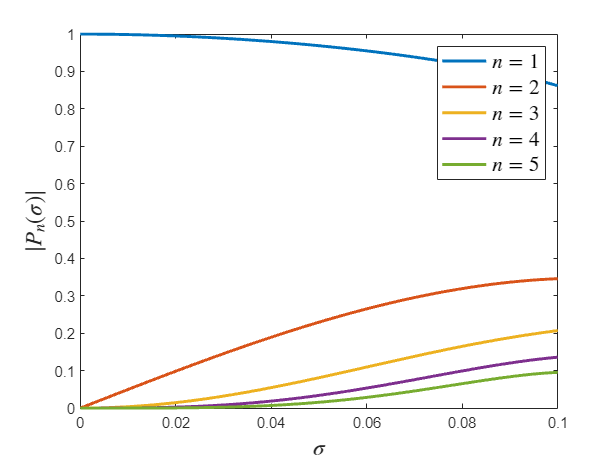

% fig = figure('Visible', 'on');

% plot(xi,abs(result.p0(:,i)),'LineWidth',2);

% for i=1:3
%   plot(xi,abs(result.p(:,i)),'LineWidth',2);  
%   hold on;  
% end
% xlabel('$\xi$','fontsize',ft_size,'Interpreter',"latex");
% ylabel('$|P_n(\xi)|$','fontsize',ft_size,'Interpreter',"latex");
% legend_n = {'$n=1$','$n=2$','$n=3$'};
% % legend_n = {'$n=1$','$n=2$','$n=3$','$n=4$','$n=5$'};
% legend(legend_n,'interpreter','latex','fontsize',14);
% xlim([min(xi) max(xi)])

figure()
for i= n0:n0:n0*5
  plot(xi*Dimfact,abs(result.p(:,i)),'LineWidth',2);  
  hold on;  
end
xlabel('$\sigma$','fontsize',ft_size,'Interpreter',"latex");
ylabel('$|P_n(\sigma)|$','fontsize',ft_size,'Interpreter',"latex");
% legend_n = {'$n=1$','$n=2$','$n=3$'};
legend_n = {'$n=1$','$n=2$','$n=3$','$n=4$','$n=5$'};
legend(legend_n,'interpreter','latex','fontsize',14);
ylim([0 1])
xlim([0 0.1])

### E. Amplitude and relative error w.r.t order of \epsilon at \sigma = 1

figure()
amp_n_1 = [1 0.875 0.875 0.8802 0.8802 0.8697 0.8697 0.8716 0.8716 0.8620]

amp_n_1 =     1.0000    0.8750    0.8750    0.8802    0.8802    0.8697    0.8697    0.8716    0.8716    0.8620


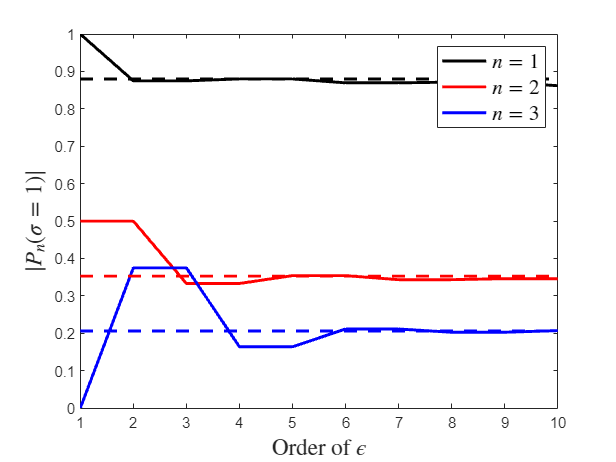

amp_n_2 = [0.5 0.5 0.3332 0.3332 0.3542 0.3542 0.3434 0.3434 0.3461 0.3461];
amp_n_3 = [0 0.375 0.375 0.164 0.164 0.2115 0.2115 0.2028 0.2028 0.2072];
fubini_1 = 0.880101*ones(1,length(amp_n_1));
fubini_2 = 0.352834*ones(1,length(amp_n_1));
fubini_3 = 0.206042*ones(1,length(amp_n_1));

plot(1:10,amp_n_1,'k','LineWidth',2);  
hold on;  
plot(1:10,amp_n_2,'r','LineWidth',2);  
hold on;  
plot(1:10,amp_n_3,'b','LineWidth',2);  
hold on;  
plot(1:10,fubini_1,'k--','LineWidth',2);  
hold on;  
plot(1:10,fubini_2,'r--','LineWidth',2);  
hold on;  
plot(1:10,fubini_3,'b--','LineWidth',2);  
hold on;   

xlabel('Order of $\epsilon$','fontsize',ft_size,'Interpreter',"latex");
ylabel('$|P_n(\sigma=1)|$','fontsize',ft_size,'Interpreter',"latex");
legend_n = {'$n=1$','$n=2$','$n=3$'};
legend(legend_n,'interpreter','latex','fontsize',14);

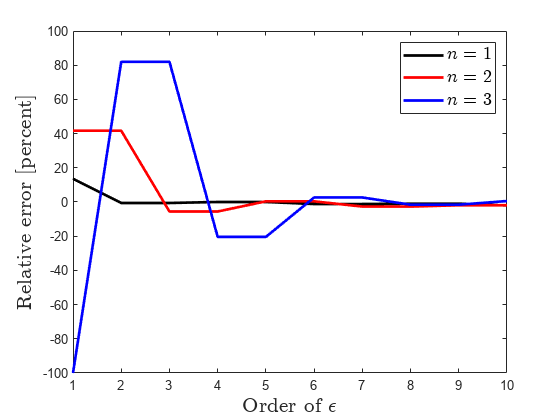


figure()
relative_error_n_1 = (amp_n_1 - fubini_1)./fubini_1*100;
relative_error_n_2 = (amp_n_2 - fubini_2)./fubini_2*100;
relative_error_n_3 = (amp_n_3 - fubini_3)./fubini_3*100;

plot(1:10,relative_error_n_1 ,'k','LineWidth',2);  
hold on;  
plot(1:10,relative_error_n_2,'r','LineWidth',2);  
hold on;  
plot(1:10,relative_error_n_3,'b','LineWidth',2);  
hold on;   
xlabel('Order of $\epsilon$','fontsize',ft_size,'Interpreter',"latex");
ylabel('Relative error [percent]','fontsize',ft_size,'Interpreter',"latex");
% legend_n = {'$n=1$','$n=2$','$n=3$'};
legend_n = {'$n=1$','$n=2$','$n=3$'};
legend(legend_n,'interpreter','latex','fontsize',14);


% observ_sigma = 0.99;
% find_observ_point = find(abs(sigma-observ_sigma) < 0.0008);
% figure_waveform = figure('visible','on');
% %plot((theta-pi)*f0,wafeForm(find_observ_point,:),'linewidth',1.5,'color','black');
% plot(theta,wafeForm(find_observ_point,:),'linewidth',1.5,'color','black');
% %plot((theta-pi)*f0,wafeForm(1,:),'linewidth',1.5,'color','black')6
% xlabel('$\theta$','fontsize',ft_size,'Interpreter','latex')
% ylabel('$P(\sigma, \theta)$','fontsize',ft_size,'Interpreter','latex')
% title('Burgers','fontsize',ft_size,'Interpreter','latex')
% plot_set; grid off;
% sigma_string = num2str(observ_sigma);
% waveformLegend = Legend_sigma(eval(sigma_string));
% legend(waveformLegend)
% %ylim([-1 1])
% %xlim([-50*pi 50*pi])
% %xticks(linspace(-50*pi,50*pi,5));
% %xticklabels({'-50\pi','-25\pi','0','25\pi','50\pi'})
% xlim([-pi pi])
% xticks([-pi:pi/2:pi])
% xticklabels({'-\pi','-\pi/2','0','\pi/2','\pi'})


## 1D lossless mono-frequency source condition using dirac delta function

For simplicity, diffusivity term will be neglected.

Assume that $$$
\hat{P}_{0}(0 ; n_0)  = 1
$$$,


$$$$
\hat{S}_{(0, 0)}(\xi ; n)  
 =(j 2\pi n) \cdot \int_{-\infty}^{\infty}  \hat{P}_{0}(\xi ; v) \cdot \hat{P}_{0}(\xi ; n-v) d v \\
 =(j 2\pi n) \cdot \int_{-\infty}^{\infty}  \hat{P}_{0}(0 ; v) \cdot \hat{P}_{0}(0 ; n-v) d v 
 =(j 2\pi n) \cdot \sum_{q=-\infty}^{\infty} \hat{P}_{0}(0 ; q) \hat{P}_{0}(0 ; n-q) \\
= \begin{cases}
    j 4\pi n_0 ,& n = 2n_0 \\
    0,              & \text{otherwise}
\end{cases}

$$$$


Since $\hat{P}_{1}(\xi ; n)=\frac{\beta}{2} \int_{0}^{\xi} \hat{S}_{(0,0)}(\zeta ; n)  d \zeta 
$, 

$\hat{P}_{1}(\xi ; 2n_0)=\frac{\beta}{2} \int_{0}^{\xi} j 4\pi n_0   d \zeta = j \beta 2\pi n_0 \xi

$.

otherwise, that is $n \neq
2n_0$, $\hat{P}_{1}(\xi ; n) = 0$. it means that $\hat{S}_{(0, 0)}(\xi ; n)  $ related to 1st order of $\varepsilon$ term makes only the second harmonic component and is proportional to 

Next, we consider the 2nd order of $\varepsilon$ term :


$$$$
\hat{S}_{(1, 0)}(\xi ; n)  
 =(j 2\pi n) \cdot \int_{-\infty}^{\infty}  \hat{P}_{0}(\xi ; v) \cdot \hat{P}_{1}(\xi ; n-v) d v 
 = \begin{cases}
    - (2\pi n_0)^2 \beta \xi ,& n = n_0 \\
    - 3(2\pi n_0)^2 \beta  \xi ,& n = 3n_0 \\
    0,              & \text{otherwise}
\end{cases}

$$$$


Since $$\hat{P}_{2}(\xi ; n)=\frac{\beta}{2}\int_{0}^{\xi} 2 \hat{S}_{(1,0)}(\zeta ; n) d \zeta$$,

$\begin{cases}
\hat{P}_{2}(\xi ; n_0)= -\frac{\beta}{2} \int_{0}^{\xi} 2(2\pi n_0)^2 \beta \zeta  d \zeta  =  -\frac{\beta^2}{2} (2\pi n_0 \xi)^2 ,& \quad n = n_0\\
\hat{P}_{2}(\xi ; 3n_0)= -\frac{\beta}{2} \int_{0}^{\xi} 6(2\pi n_0)^2 \beta \zeta  d \zeta  =  -\frac{3\beta^2}{2} (2\pi n_0 \xi)^2 ,& \quad  n = 3n_0\\

\end{cases}$.

Next, we will derive the 3rd order of $\varepsilon$ term :


$$$$
\hat{S}_{(2, 0)}(\xi ; n)  
 =(j 2\pi n) \cdot \int_{-\infty}^{\infty}  \hat{P}_{0}(\xi ; v) \cdot \hat{P}_{2}(\xi ; n-v) d v 
 = \begin{cases}
    - j4(2\pi n_0)^3 \beta^2 \xi^2 ,& n = 2n_0 \\
    - j6(2\pi n_0)^3 \beta^2  \xi^2 ,& n = 4n_0 \\
    0,              & \text{otherwise}
\end{cases}

$$$$


and


$$$$
\hat{S}_{(1, 1)}(\xi ; n)  
 =(j 2\pi n) \cdot \int_{-\infty}^{\infty}  \hat{P}_{1}(\xi ; v) \cdot \hat{P}_{1}(\xi ; n-v) d v \\
 = \begin{cases}
    - j4(2\pi n_0)^3 \beta^2  \xi^2 ,& n = 4n_0 \\
    0,              & \text{otherwise}
\end{cases}
$$$$


Since $\hat{P}_{3}(\xi ; n)=\frac{\beta}{2}\int_{0}^{\xi}\left[2 \hat{S}_{(2,0)}(\zeta ; n)+\hat{S}_{(1,1)}(\zeta ; n)\right]  d \zeta$,


$$\begin{cases}
\hat{P}_{3}(\xi ; 2n_0) =  -j\frac{4\beta^3}{3} (2\pi n_0 \xi)^3 ,&  \quad n = 2n_0\\
\hat{P}_{3}(\xi ; 4n_0)=  -j\frac{8\beta^3}{3} (2\pi n_0 \xi)^3 ,& \quad  n = 4n_0\\

\end{cases}$$


Finally, we will derive the 4th order of $\varepsilon$ term :


$$$$
\hat{S}_{(3, 0)}(\xi ; n)  
 =(j 2\pi n) \cdot \int_{-\infty}^{\infty}  \hat{P}_{0}(\xi ; v) \cdot \hat{P}_{3}(\xi ; n-v) d v 
 = \begin{cases}
    \frac{4}{3} \beta^3 (2\pi n_0)^4  \xi^3 ,& n = n_0 \\
    12 \beta^3 (2\pi n_0)^4  \xi^3 ,& n = 3n_0 \\
    \frac{40}{3} \beta^3 (2\pi n_0)^4  \xi^3 ,& n = 5n_0 \\
    0,              & \text{otherwise}
\end{cases}

$$$$


and


$$$$
\hat{S}_{(2, 1)}(\xi ; n)  
 =(j 2\pi n) \cdot \int_{-\infty}^{\infty}  \hat{P}_{1}(\xi ; v) \cdot \hat{P}_{2}(\xi ; n-v) d v 
 = \begin{cases}
    -3 \beta^3 (2\pi n_0)^4  \xi^3 ,& n = n_0 \\
    \frac{3}{2} \beta^3 (2\pi n_0)^4  \xi^3 ,& n = 3n_0 \\
    \frac{15}{2} \beta^3 (2\pi n_0)^4  \xi^3 ,& n = 5n_0 \\
    0,              & \text{otherwise}
\end{cases}

$$$$


Since $\hat{P}_{4}(\xi ; n)=\frac{\beta}{2}\int_{0}^{\xi}\left[2 \hat{S}_{(3,0)}(\zeta ; n)+2\hat{S}_{(2,1)}(\zeta ; n)\right]  d \zeta$,

$\begin{cases}
\hat{P}_{4}(\xi ; n_0) =  -\frac{5}{12} \beta^4 (2\pi n_0 \xi)^4 ,&  \quad n = n_0\\
\hat{P}_{4}(\xi ; 3n_0)=  \frac{27}{8} \beta^4 (2\pi n_0 \xi)^4 ,& \quad  n = 3n_0\\
\hat{P}_{4}(\xi ; 5n_0)=  \frac{125}{24} \beta^4 (2\pi n_0 \xi)^4 ,& \quad  n = 5n_0\\
\end{cases}$.

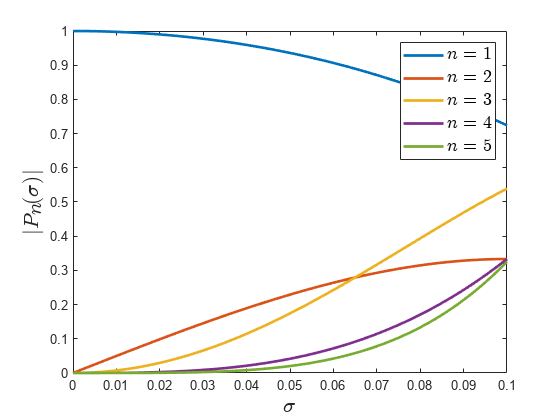

Analytical_result.p = result.p0;
Analytical_result.p(:,2*n0) = epsilon*1j*beta*(2*pi*n0*xi); % p1(xi;2n_0)

Analytical_result.p(:,n0) = Analytical_result.p(:,n0)-epsilon^2*beta^2*(2*pi*n0*xi').^2; % p2(xi;n_0)
Analytical_result.p(:,3*n0) = Analytical_result.p(:,3*n0)-3*epsilon^2*beta^2*(2*pi*n0*xi').^2; % p2(xi;3n_0)

Analytical_result.p(:,2*n0) = Analytical_result.p(:,2*n0)-1j*4/3*epsilon^3*beta^3*(2*pi*n0*xi').^3; % p3(xi;2n_0)
Analytical_result.p(:,4*n0) = Analytical_result.p(:,4*n0)-1j*8/3*epsilon^3*beta^3*(2*pi*n0*xi').^3; % p3(xi;4n_0)

Analytical_result.p(:,n0) = Analytical_result.p(:,n0)-5/12*epsilon^4*beta^4*(2*pi*n0*xi').^4; % p4(xi;n_0)
Analytical_result.p(:,3*n0) = Analytical_result.p(:,3*n0)+27/8*epsilon^4*beta^4*(2*pi*n0*xi').^4; % p4(xi;3n_0)
Analytical_result.p(:,5*n0) = Analytical_result.p(:,5*n0)+125/24*epsilon^4*beta^4*(2*pi*n0*xi').^4; % p4(xi;5n_0)

figure()
for i= n0:n0:n0*5
  plot(xi*Dimfact,abs(Analytical_result.p(:,i)),'LineWidth',2);  
  hold on;  
end
xlabel('$\sigma$','fontsize',ft_size,'Interpreter',"latex");
ylabel('$|P_n(\sigma)|$','fontsize',ft_size,'Interpreter',"latex");
% legend_n = {'$n=1$','$n=2$','$n=3$'};
legend_n = {'$n=1$','$n=2$','$n=3$','$n=4$','$n=5$'};
legend(legend_n,'interpreter','latex','fontsize',14);
ylim([0 1])
xlim([0 0.1])


% 
% if order >= 1 % 1st order    
%     source.S00 = Sub_Convolution(result.p0,result.p0);
%     result.p1 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(source.S00,xi,N,delta_0);
%     result.p = result.p0 + epsilon*result.p1;
%     if order >= 2 % 2nd order            
%         source.S10 = Sub_Convolution(result.p1,result.p0);
%         result.p2 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S10,xi,N,delta_0); 
%         result.p = result.p + epsilon^2*result.p2;
%         if order >= 3 % 3rd order       
%             source.S20 = Sub_Convolution(result.p2,result.p0);
%             source.S11 = Sub_Convolution(result.p1,result.p1);
%             result.p3 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S20+source.S11,xi,N,delta_0); 
%             result.p = result.p + epsilon^3*result.p3;
%             if order >= 4 % 4th order       
%             source.S30 = Sub_Convolution(result.p3,result.p0);
%             source.S21 = Sub_Convolution(result.p2,result.p1);
%             result.p4 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S30+2*source.S21,xi,N,delta_0); 
%             result.p = result.p + epsilon^4*result.p4;
%                 if order >= 5 % 5th order       
%                 source.S40 = Sub_Convolution(result.p4,result.p0);
%                 source.S31 = Sub_Convolution(result.p3,result.p1);
%                 source.S22 = Sub_Convolution(result.p2,result.p2);
%                 result.p5 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S40+2*source.S31+source.S22,xi,N,delta_0); 
%                 result.p = result.p + epsilon^5*result.p5;
%                     if order >= 6 % 6th order 
%                         source.S50 = Sub_Convolution(result.p5,result.p0);
%                         source.S41 = Sub_Convolution(result.p4,result.p1);
%                         source.S32 = Sub_Convolution(result.p3,result.p2);
%                         result.p6 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S50+2*source.S41+2*source.S32,xi,N,delta_0); 
%                         result.p = result.p + epsilon^6*result.p6;
%                         if order >= 7 % 7th order 
%                             source.S60 = Sub_Convolution(result.p6,result.p0);
%                             source.S51 = Sub_Convolution(result.p5,result.p1);
%                             source.S42 = Sub_Convolution(result.p4,result.p2);
%                             source.S33 = Sub_Convolution(result.p3,result.p3);
%                             result.p7 = beta/2*exp(-2*pi^2*n.^2*delta_0.*xi.').*Sub_Integral(2*source.S60+2*source.S51+2*source.S42+source.S33,xi,N,delta_0); 
%                             result.p = result.p + epsilon^7*result.p7;
%                         end
%                     end
%                 end
%             end
%         end
%     end
% end

## Implementation of the discrete convolution using shape function's properties

Let $  \[ \hat{P}(\xi ; n)= \sum\limits_{q=-\infty}^{\infty} \hat{P}(\xi ; q) \cdot \varphi_{q}(n) \] 
$

where 


$$$$
\varphi_{q}(v)=\left\{\begin{array}{cc}
v-q+1 & \text { if } q-1 \leq v \leq q \\
q-v+1 & \text { if } q \leq v \leq q+1 \\
0 & \text { otherwise }
\end{array} .\right.
$$$$


The source term can be rewritten by above the relationship of shape function:


$$$$

\hat{S}_{(l, m)}(\xi ; n)  =(j 2\pi n)  \cdot\left[\hat{P}_{l}(\xi ; n) \underset{(n)}{*} \hat{P}_{m}(\xi ; n)\right] \\
 =(j 2\pi n) \cdot \int_{-\infty}^{\infty} \sum_{q=-\infty}^{\infty} \hat{P}_{l}(\xi ; q) \varphi_{q}(v) \cdot \sum_{r=-\infty}^{\infty} \hat{P}_{m}(\xi ; r) \varphi_{r}(n-v) d v \\
 =(j 2\pi n) \cdot \sum_{q=-\infty}^{\infty} \sum_{r=-\infty}^{\infty} \hat{P}_{l}(\xi ; q) \hat{P}_{m}(\xi ; r) \int_{-\infty}^{\infty} \varphi_{q}(v) \varphi_{r}(n-v) d v .

$$$$


Note that $$\varphi_{q}(v)$$ have the following interesting property for any integer $$n$$ :

(i) If $$q+r=n-1$$,

$$\varphi_{q}(v)$$ is zero except that $$q-1 \leq v \leq q+1$$.

$$\varphi_{r}(n-v)$$ is zero except that $$q \leq v \leq q+2$$.

Hence, $$\int_{-\infty}^{\infty} \varphi_{q}(v) \cdot \varphi_{r}(n-v) d v=\int_{q}^{q+1} \varphi_{q}(v) \cdot \varphi_{n-q-1}(n-v) d v = \frac{1}{6}$$.

(ii) If $$q+r=n$$,

$$\varphi_{q}(v)$$is zero except that $$q-1 \leq v \leq q+1$$.

$$\varphi_{r}(n-v)$$  is zero except that $$q-1 \leq v \leq q+1$$.

Hence, $$\int_{-\infty}^{\infty} \varphi_{q}(v) \cdot \varphi_{r}(n-v) d v=\int_{q-1}^{q+1} \varphi_{q}(v) \cdot \varphi_{n-q}(n-v) d v= \frac{2}{3}$$.

(iii) If $$q+r=n+1$$,

$$\varphi_{q}(v)$$ is zero except that $$q-1 \leq v \leq q+1$$.

$$\varphi_{r}(n-v)$$ is zero except that $$q-2 \leq v \leq q$$.

Hence, $$\int_{-\infty}^{\infty} \varphi_{q}(v) \cdot \varphi_{r}(n-v) d v=\int_{q-1}^{q} \varphi_{q}(v) \cdot \varphi_{n-q+1}(n-v) d v= \frac{1}{6}$$.

Therefore,


$$$$
\hat{S}_{(l, m)}(\xi ; n)=  (j 2\pi n) \cdot \sum_{q=-\infty}^{\infty} \sum_{r=-\infty}^{\infty} \hat{P}_{l}(\xi ; q) \hat{P}_{m}(\xi ; r) \int_{-\infty}^{\infty} \varphi_{q}(v) \varphi_{r}(n-v) d v \\
=  (j 2\pi n) \cdot \sum_{q=-\infty}^{\infty}\left\{\begin{array}{l}
\hat{P}_{l}(\xi ; q) \hat{P}_{m}(\xi ; n-q+1) \int_{q-1}^{q} \varphi_{q}(v) \varphi_{n-q+1}(n-v) d v \\
+\hat{P}_{l}(\xi ; q) \hat{P}_{m}(\xi ; n-q) \int_{q-1}^{q+1} \varphi_{q}(v) \varphi_{n-q}(n-v) d v \\
+\hat{P}_{l}(\xi ; q) \hat{P}_{m}(\xi ; n-q-1) \int_{q}^{q+1} \varphi_{q}(v) \varphi_{n-q -1}(n-v) d v
\end{array}\right\} \\
=  \frac{j \pi n}{3} \cdot \sum_{q=-\infty}^{\infty}\left\{\begin{array}{l}
\hat{P}_{l}(\xi ; q) \cdot \hat{P}_{m}(\xi ; n-q+1) \\
+4  \hat{P}_{l}(\xi ; q) \cdot \hat{P}_{m}(\xi ; n-q) \\
+\hat{P}_{l}(\xi ; q) \cdot \hat{P}_{m}(\xi ; n-q-1) 
\end{array}\right\} \\
\approx \frac{j \pi n}{3} \cdot \sum_{q=-N}^{N}
\hat{P}_{l}(\xi ; q) 
\{\hat{P}_{m}(\xi ; n-q+1) +4   \hat{P}_{m}(\xi ; n-q) + \hat{P}_{m}(\xi ; n-q-1) \}
$$$$
